# EEG Data Preprocessing

## Loading Dataset

% Initialize Data Parameters

fs = 256; % sample rate in Hz
testNodes = ["Cz","F4"];
H_CzF4 = EEGData(FC(1:6),testNodes,fs);
A_CzF4 = EEGData(FADHD(1:6),testNodes,fs);

Subjectnum = 1;
Channel = 1;

H_Test1 = H_CzF4.Task(1);
A_Test1 = A_CzF4.Task(1);

H_subject = subject(1,1);
A_subject = subject(1,0);

H_subject.Data = H_Test1.getSubjectData(H_subject.Id,"Cz");

A_subject.Data = A_Test1.getSubjectData(A_subject.Id,"Cz");

## Data Filtering

The first step in processing the data    

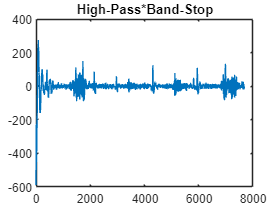

ButterHP = designfilt('highpassiir', ...
    'StopbandFrequency',1, ...
    'PassbandFrequency',2, ...
    'StopbandAttenuation',60, ...
    'PassbandRipple',1, ...
    'SampleRate',256);

ButterBP = designfilt('bandpassiir', ...
    'StopbandFrequency1',1, ...
    'PassbandFrequency1',2, ...
    'PassbandFrequency2',40, ...
    'StopbandFrequency2',41, ...
    'StopbandAttenuation1',60, ...
    'PassbandRipple',1, ...
    'StopbandAttenuation2',60, ...
    'SampleRate',256);

ButterBS = designfilt('bandstopiir', ...
    'PassbandFrequency1',49, ...
    'StopbandFrequency1',50, ...
    'StopbandFrequency2',60, ...
    'PassbandFrequency2',61, ...
    'PassbandRipple1',1, ...
    'StopbandAttenuation',60, ...
    'PassbandRipple2',1, ...
    'SampleRate',256);

padlen = 256;
padded = [flip(H_subject.Data(1:padlen)) H_subject.Data flip(H_subject.Data(end-padlen+1:end))];


H_HPfiltered = filtfilt(ButterHP,padded);
H_HPfiltered =H_HPfiltered(padlen+1:end-padlen);
H_Combofiltered = filtfilt(ButterHP,filtfilt(ButterBS,padded));
H_Combofiltered = H_Combofiltered(padlen+1:end-padlen);
H_BPfiltered = filtfilt(ButterBP,padded);
H_BPfiltered =H_BPfiltered(padlen+1:end-padlen);

plot(H_Combofiltered);
title("High-Pass*Band-Stop");

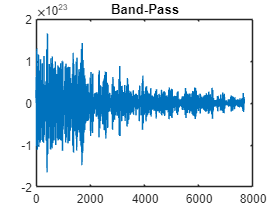


plot(H_BPfiltered)
title("Band-Pass")

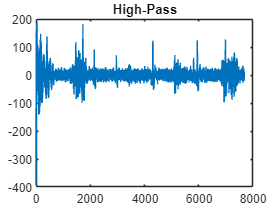


plot(H_HPfiltered);
title("High-Pass");

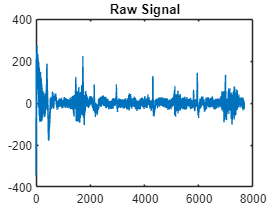


plot(H_subject.Data);
title("Raw Signal");